## HMRF-GMM-EM Segmentation

**Author: **Harshit Varma

*(Run this live script cell by cell for testing)*

clear variables;
clc;

Load the given data

DATA_PATH = "../data/data.mat";
data = load(DATA_PATH, "-mat");
img  = data.imageData;
mask = data.imageMask;

Display the data and save as JPG for easier access:

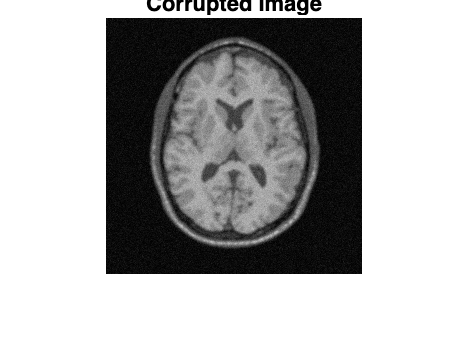

imshow(img);
title("Corrupted Image");
saveas(gcf, "../plots/corrupted.jpg", "jpg");

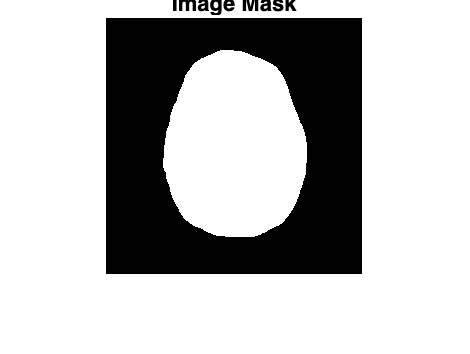


% We only need to segment inside the brain, the background-foreground
% segmentation is already provided by the mask
imshow(mask);
title("Image Mask");
saveas(gcf, "../plots/mask.jpg", "jpg");

% The number of categories for the segmentation (gray matter, white matter and CSF)
k = 3; 

% Get the background (bg) and the foreground (fg) masks
mask_fg = (mask == 1);
mask_bg = (mask == 0);

Set the background values to 0 since we don't need them

This also helps us see the segmentation better

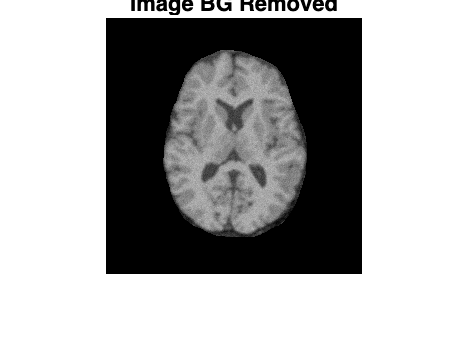

img(mask_bg) = 0;
imshow(img);
title("Image BG Removed");

### **Initial Segmentation using K-Means**

We use the standard K-Means algorithm for obtaining the initial segementation, since it's simple, fast and gives a good quality initial estimate. 

The initial class means and the standard deviation estimates are obtained from the initial label image by computing the sample means and the sample standard deviations for each class.

% Get the inital segmented image using K-Means algorithm
eps = 1e-5;
[seg_init, mu_init, sigma_init] = KMeans(img, mask, k, eps);

'datasample' requires Statistics and Machine Learning Toolbox.

Error in KMeans (line 25)
    mu = datasample(fg, k, 'Replace', false);


% Show and save the initial segmented image 
showSegmented(seg_init, k, "Inital Image: Using K-Means", "../plots/segment_kmeans.jpg");

As observed, the inital selected means are all near the 3 (local) modes of the histogram

histogram(img(mask_fg), 100);
for i = 1:k
    xline(mu_init(i), "-.r", 'LineWidth', 2);
end
title("Quality of the initial segmentation");

### The EM Algorithm

beta = 0.75; % This gave the best looking results
eps_EM = 1e-7;
N_EM_max = 40; % Specifies the max no. of iterations of EM
N_ICM = 10; % The number of times we run ICM

fprintf("Starting the EM Optimization\n");
[seg, memberships, mu, sigma] = EM(seg_init, img, mask, k, mu_init, sigma_init, beta, eps_EM, N_ICM, N_EM_max);
showSegmented(seg, k, "Optimal Label Image for the chosen Beta", "../plots/segment_em.jpg");

The optimal class memberships for the chosen beta

for i = 1:k
    m = memberships(:, :, i);
    figure;
    imshow(m);
    title(sprintf("Opt. Memberships for chosen Beta: Class %d", i));
    saveas(gcf, sprintf("../plots/memberships_%d.jpg", i), "jpg");
end

### Without MRF Prior

beta = 0;
[seg_no_mrf, memberships_no_mrf, mu_no_mrf, sigma_no_mrf] = EM(seg_init, img, mask, k, mu_init, sigma_init, beta, eps_EM, N_ICM, N_EM_max);
showSegmented(seg_no_mrf, k, "Optimal Label Image for Beta = 0", "../plots/segment_em_no_mrf.jpg");

for i = 1:k
    m = memberships_no_mrf(:, :, i);
    figure;
    imshow(m);
    title(sprintf("Opt. Memberships for Beta = 0: Class %d", i));
    saveas(gcf, sprintf("../plots/memberships_no_mrf_%d.jpg", i), "jpg");
end